# Test Case - Motor Drive Unit

mdl = "MotorDriveUnit_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
MotorDriveUnit_Component_harness_params

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters
simIn = setBlockParameter(simIn, mdl+"/Axle clutch switch", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle clutch switch", Time="10");
simIn = setBlockParameter(simIn, mdl+"/Axle clutch switch", After="0");
simIn = setBlockParameter(simIn, mdl+"/Axle speed", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle speed", Time="10");
simIn = setBlockParameter(simIn, mdl+"/Axle speed", After="0");
simIn = setBlockParameter(simIn, mdl+"/Axle torque", Before="-10");
simIn = setBlockParameter(simIn, mdl+"/Axle torque", Time="400");
simIn = setBlockParameter(simIn, mdl+"/Axle torque", After="0");
simIn = setBlockParameter(simIn, mdl+"/Motor torque command", Before="150");
simIn = setBlockParameter(simIn, mdl+"/Motor torque command", Time="300");
simIn = setBlockParameter(simIn, mdl+"/Motor torque command", After="-50");

% Initial conditions
simIn = setBlockParameter(simIn, mdl+"/Mechanical Load/Load Inertia", w="0");

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "600");

% Run simulation
simOut = sim(simIn);

## Visualize Simulation Result

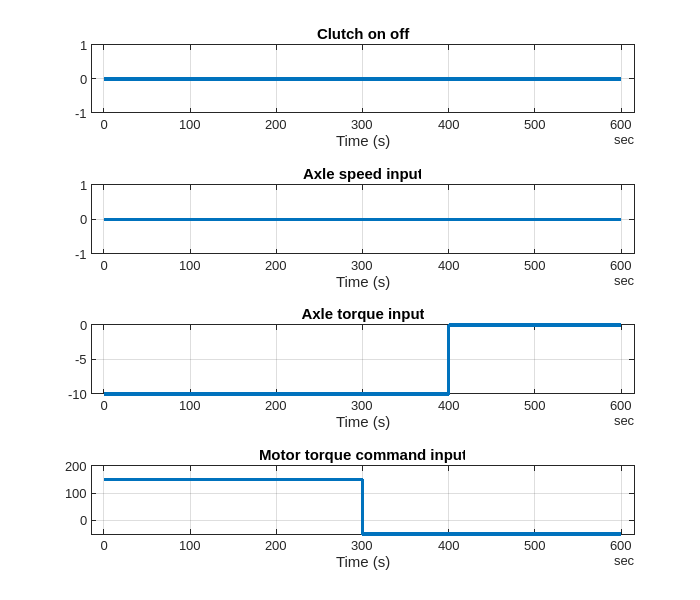

simData = extractTimetable(simOut.logsout);

MotorDriveUnit_Component_plotResultInputs(SimData = simData);

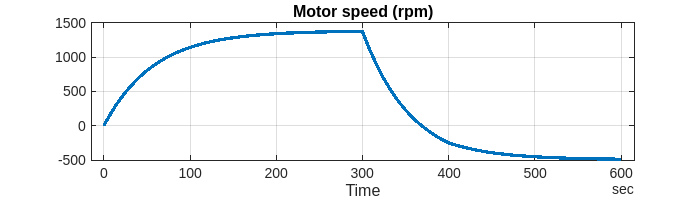

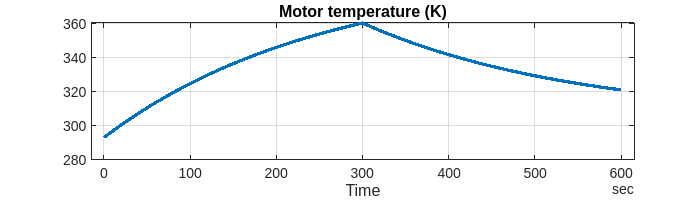

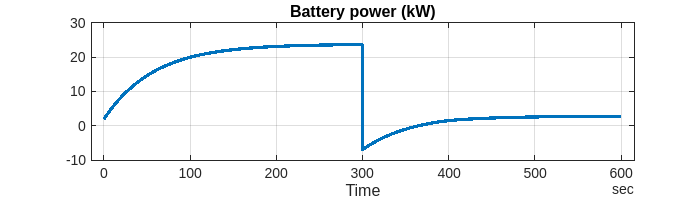

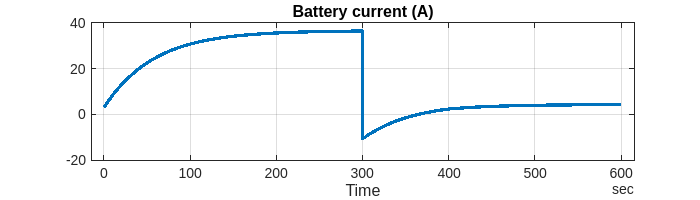

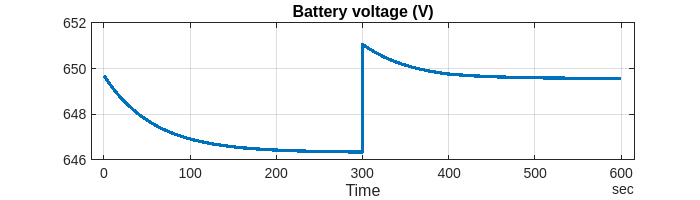

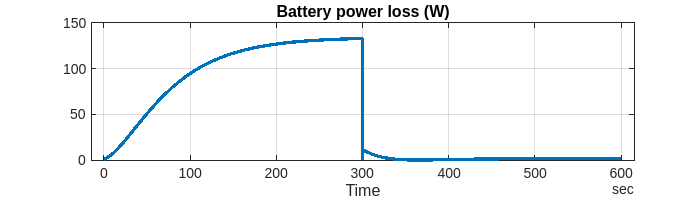

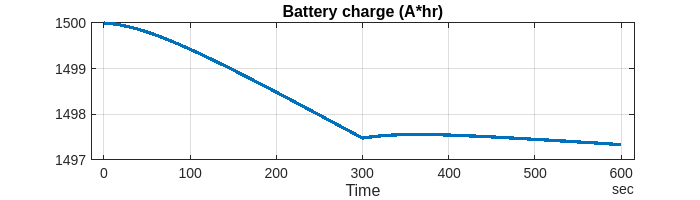

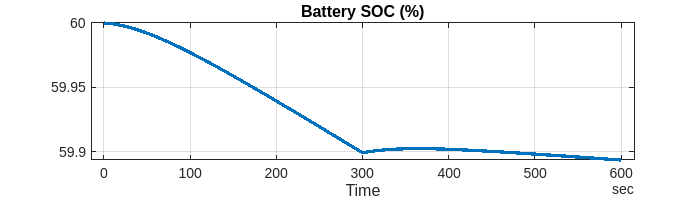

MotorDriveUnit_Component_plotResultOutputs(SimData = simData, FigureHeight = 200);

*Copyright 2021-2022 The Mathworks, Inc.*